DAC Range

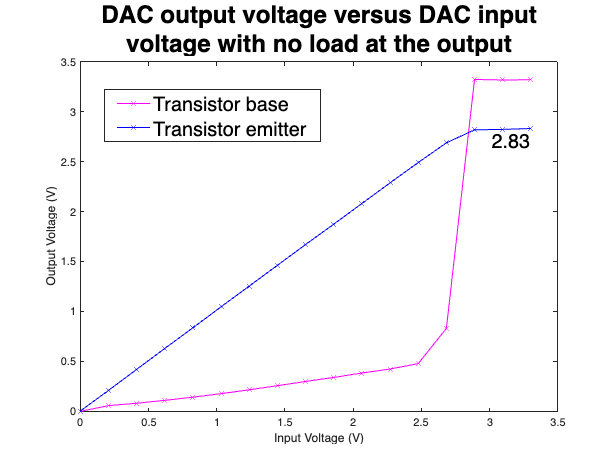

dac_input = [0 0.206451612903226 0.412903225806452 0.619354838709677 0.825806451612903 1.03225806451613 1.23870967741935 1.44516129032258 1.65161290322581 1.85806451612903 2.06451612903226 2.27096774193548 2.47741935483871 2.68387096774194 2.89032258064516 3.09677419354839 3.3];

dac_unbuff_no_load = [0.00029 0.05771 0.08159 0.1104 0.14257 0.17767 0.21611 0.25702 0.29951 0.3399 0.38418 0.42398 0.47831 0.8307 3.3212 3.3161 3.318];
dac_buff_no_load = [0.00384 0.20963 0.42009 0.6297 0.8366 1.0469 1.2543 1.462 1.6696 1.8732 2.0801 2.287 2.4899 2.6869 2.8172 2.8217 2.8304];

dac_unbuff_loaded = [0.00029 0.8202 1.0443 1.2606 1.4713 1.6842 1.8941 2.0981 2.307 2.5125 2.7173 2.9261 3.131 3.2658 3.262 3.252 3.2683];
dac_buff_loaded = [0.00002 0.20509 0.41189 0.6178 0.8227 1.0291 1.2318 1.4325 1.6364 1.8371 2.0325 2.2334 2.4415 2.5491 2.5788 2.579 2.5854];

figure();
plot(dac_input, dac_unbuff_no_load, 'm-x', dac_input, dac_buff_no_load, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output voltage versus DAC input", "voltage with no load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_no_load(end), sprintf('%.2f', dac_buff_no_load(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_no_load.png');

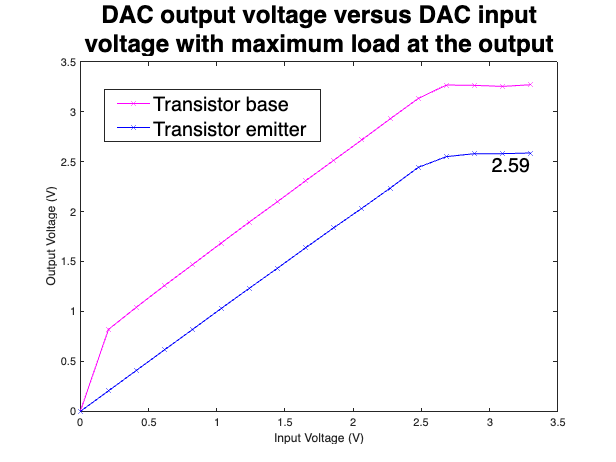


figure();
plot(dac_input, dac_unbuff_loaded, 'm-x', dac_input, dac_buff_loaded, 'b-x');
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title(["DAC output voltage versus DAC input", "voltage with maximum load at the output"], "FontSize", 22);
legend(["Transistor base", "Transistor emitter"], "Position", [0.17 0.7 0.35, 0.1], "FontSize", 18);
text(dac_input(end), dac_buff_loaded(end), sprintf('%.2f', dac_buff_loaded(end)), 'HorizontalAlignment', 'right', 'VerticalAlignment', 'top', 'FontSize', 18);
saveas(gcf, 'Report/Figures/Testing/DAC_loaded.png');


dac_input = dac_input(1:13);
dac_buff_no_load = dac_buff_no_load(1:13);
dac_buff_loaded = dac_buff_loaded(1:13);

coefficients_no_load = polyfit(dac_input, dac_buff_no_load, 1);
m_no_load = coefficients_no_load(1)

m_no_load = 1.0048

b_no_load = coefficients_no_load(2)

b_no_load = 0.0063

r = corrcoef(dac_input, dac_buff_no_load);
r_2_no_load = r(1,2)^2

r_2_no_load = 1.0000


coefficients_no_load = polyfit(dac_input, dac_buff_loaded, 1);
m_loaded = coefficients_no_load(1)

m_loaded = 0.9837

b_loaded = coefficients_no_load(2)

b_loaded = 0.0070

r = corrcoef(dac_input, dac_buff_loaded);
r_2_loaded = r(1,2)^2

r_2_loaded = 1.0000

ADC range

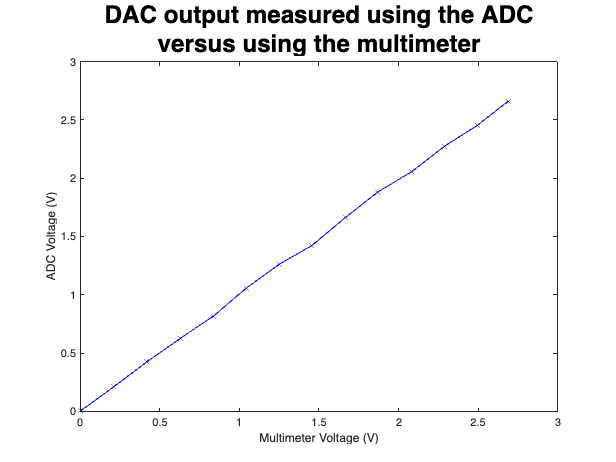

adc_multimeter = [0.00299 0.20852 0.41849 0.6282 0.8363 1.0419 1.2487 1.4556 1.6649 1.8689 2.0821 2.2859 2.4966 2.6888];
adc_bits = [0.00483516483516484 0.20952380952381 0.425494505494506 0.626153846153846 0.817142857142857 1.05648351648352 1.26117216117216 1.42315018315018 1.66168498168498 1.88087912087912 2.05575091575092 2.27172161172161 2.45465201465201 2.66095238095238];

figure();
plot(adc_multimeter, adc_bits, 'b-x');
xlabel('Multimeter Voltage (V)');
ylabel('ADC Voltage (V)');
title(["DAC output measured using the ADC", "versus using the multimeter"], "FontSize", 22);
saveas(gcf, 'Report/Figures/Testing/ADC.png');


coefficients_adc = polyfit(adc_multimeter, adc_bits, 1);
m_adc = coefficients_adc(1)

m_adc = 0.9877

b_adc = coefficients_adc(2)

b_adc = 0.0082

r = corrcoef(adc_multimeter, adc_bits);
r_adc = r(1,2)^2

r_adc = 0.9997

Resistors

R = [0.02 1 1.21 1.52 1.88 2.26 2.68 3.42 3.85 4.84 5.59 6.72 7.49 8.2 9.9];
vr_ave = [1.04 1.95 2.13 2.42 2.7 3.06 3.45 4.09 4.48 5.35 5.96 6.91 7.52 8.09 9.39]/5;
vr_sin = [1.03 1.94 2.11 2.4 2.69 3.04 3.44 4.08 4.47 5.35 5.96 6.91 7.52 8.1 9.4]/5;

r = corrcoef(vr_ave, vr_sin);
r_r = r(1,2)^2

r_r = 1.0000


k = vr_ave * 5/105;
rm = k*100./(1-k);

% curveFitter(R, vr_ave)

r = corrcoef(R, rm);
r_rv = r(1,2)^2

r_rv = 0.9999

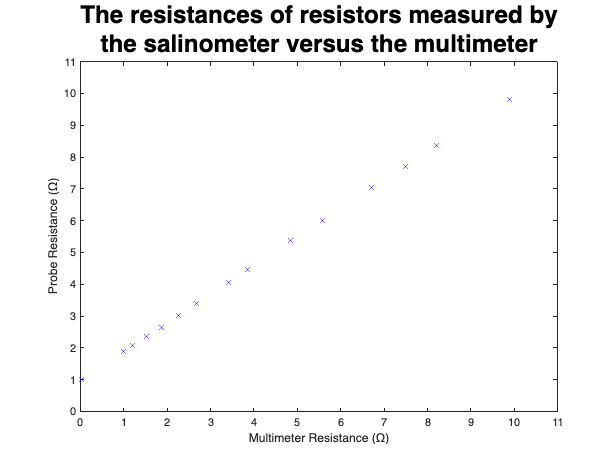


figure();
plot(R, rm, 'bx');
xlabel('Multimeter Resistance (Ω)');

ylabel('Probe Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_uncorrected.png');

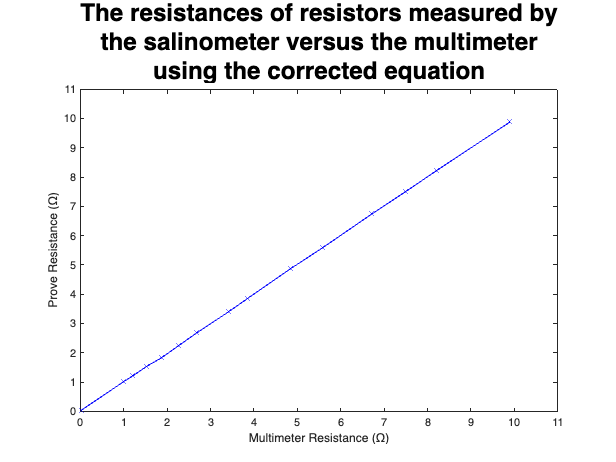


% (p1*x + p2)/(x + q1)
P1 = 17.4687;
P2 = 18.4643;
Q1 = 91.8315;

r_corr = (P2 - Q1 * vr_ave)./(vr_ave - P1);

figure();
plot(R, r_corr, 'b-x');
xlabel('Multimeter Resistance (Ω)');
ylabel('Prove Resistance (Ω)');
title(["The resistances of resistors measured by", "the salinometer versus the multimeter", "using the corrected equation"], "FontSize", 22);
xlim([0,11])
ylim([0,11])
saveas(gcf, 'Report/Figures/Testing/R_corrected.png');


coefficients_r = polyfit(R, r_corr, 1);
m_r = coefficients_r(1)

m_r = 1.0000

b_r = coefficients_r(2)

b_r = 8.4802e-05


r = corrcoef(R, r_corr);
r_r_corr = r(1,2)^2

r_r_corr = 1.0000

Voltage to Conductivity    

AuS8_dac = transpose([0.000805860805860806 0.0427106227106227 0.126520146520147 0.208717948717949 0.157142857142857 0.238534798534799 0.388424908424908 0.383589743589744 0.336043956043956 0.528644688644689 0.506886446886447 0.596336996336996 0.655970695970696 0.784102564102564 0.75025641025641 0.771208791208791 0.773626373626374 0.712380952380952 1.14915750915751 0.853406593406593 1.24021978021978 0.925128205128205 1.13626373626374 1.31919413919414 1.23941391941392 1.38608058608059 1.28534798534799 1.40380952380952 1.44490842490842 1.49809523809524 1.54886446886447 1.60446886446886 1.65604395604396 1.70761904761905 1.76 1.81318681318681 1.8647619047619 1.91553113553114 1.96791208791209 2.01948717948718 2.07106227106227 2.12263736263736 2.1774358974359 2.22901098901099 2.27978021978022 2.33216117216117 2.3829304029304 2.43369963369963 2.48608058608059 2.53684981684982]);
AuS8_measure = transpose([0.0324542124542125 0.0335531135531136 0.0312087912087912 0.0271794871794872 0.0259340659340659 0.0243223443223443 0.0232967032967033 0.0228571428571429 0.0231501831501831 0.0238095238095238 0.0243956043956044 0.0250549450549451 0.0257142857142857 0.0265201465201465 0.0272527472527472 0.027985347985348 0.0284981684981685 0.0291575091575092 0.0298168498168498 0.0306227106227106 0.0311355311355311 0.0319413919413919 0.0325274725274725 0.0331868131868132 0.0338461538461538 0.0346520146520146 0.0352380952380952 0.0358974358974359 0.0366300366300366 0.0372161172161172 0.0378754578754579 0.0385347985347985 0.0394139194139194 0.0399267399267399 0.0406593406593407 0.0412454212454212 0.041978021978022 0.0426373626373626 0.0434432234432234 0.044029304029304 0.0446886446886447 0.0453479853479853 0.0460805860805861 0.0468131868131868 0.0473992673992674 0.0480586080586081 0.0487912087912088 0.0494505494505494 0.0501098901098901 0.0507692307692308]);
AuS8_ratio = transpose([44.3 35.2307692307692 23.6666666666667 17.6666666666667 13.6153846153846 11.448275862069 9.9375 8.91428571428571 7.70731707317073 7.38636363636364 6.9375 6.70588235294118 6.26785714285714 6.03333333333333 5.72307692307692 5.61764705882353 5.32876712328767 5.16883116883117 5.28571428571429 4.97619047619048 4.7752808988764 4.68817204301075 4.67368421052631 4.62244897959184 4.52941176470588 4.4622641509434 4.37272727272727 4.29824561403509 4.23728813559322 4.16393442622951 4.136 4.109375 4.04511278195489 4.00735294117647 3.96428571428571 3.90972222222222 3.87162162162162 3.82894736842105 3.80128205128205 3.77987421383648 3.74233128834356 3.68452380952381 3.67836257309941 3.65142857142857 3.63483146067416 3.6043956043956 3.58064516129032 3.55263157894737 3.52577319587629 3.5]);
ft = fittype('A/(x+p)');
[fitresult, gof] = fit(AuS8_dac, AuS8_ratio, ft);

fitresult

fitresult =      General model:
     fitresult(x) = A/(x+p)
     Coefficients (with 95% confidence bounds):
       A =       5.104  (4.621, 5.587)
       p =      0.1131  (0.0982, 0.1279)

gof.rsquare

ans = 0.9597


AuS9a_dac = transpose([1.64556776556777 1.65846153846154 1.67860805860806 1.7003663003663 1.71728937728938 1.73904761904762 1.75919413919414 1.77772893772894 1.7970695970696 1.81399267399267 1.83252747252747 1.85186813186813 1.87040293040293 1.88974358974359 1.90908424908425 1.92761904761905 1.94695970695971 1.96388278388278 1.98161172161172 2.0025641025641 2.02190476190476 2.04043956043956 2.06139194139194 2.07831501831502 2.0992673992674 2.11538461538462 2.13472527472527 2.15326007326007 2.17421245421245 2.19355311355311 2.21289377289377 2.23142857142857 2.25157509157509 2.27010989010989 2.28703296703297 2.30556776556777 2.32490842490843 2.34505494505495 2.36358974358974 2.3829304029304 2.40227106227106 2.42161172161172 2.43692307692308 2.4570695970696 2.47641025641026 2.49655677655678 2.51509157509157 2.53362637362637 2.55377289377289 2.57311355311355]);
AuS9a_measure = transpose([0.0432234432234432 0.0437362637362637 0.0441025641025641 0.0444688644688645 0.0447619047619048 0.044981684981685 0.0452747252747253 0.0455677655677656 0.0458608058608059 0.0460805860805861 0.0463003663003663 0.0465934065934066 0.0468131868131868 0.0471062271062271 0.0473992673992674 0.0476190476190476 0.0478388278388278 0.0481318681318681 0.0483516483516484 0.0486446886446886 0.0488644688644689 0.0491575091575092 0.0495970695970696 0.0496703296703297 0.04996336996337 0.0501831501831502 0.0504761904761905 0.0506959706959707 0.050989010989011 0.0512820512820513 0.0515018315018315 0.0518681318681319 0.052014652014652 0.0523076923076923 0.0525274725274725 0.0528205128205128 0.0531135531135531 0.0533333333333333 0.0535531135531135 0.0538461538461538 0.0541391941391941 0.0543589743589744 0.0546520146520146 0.0548717948717949 0.0551648351648352 0.0553846153846154 0.0556043956043956 0.0558241758241758 0.0561904761904762 0.0564102564102564]);
AuS9a_ratio = transpose([4.46969696969697 4.48872180451128 4.49253731343284 4.46323529411765 4.42753623188406 4.41726618705036 4.41428571428571 4.4113475177305 4.37762237762238 4.36805555555555 4.32876712328767 4.3265306122449 4.31756756756757 4.28666666666667 4.28476821192053 4.2483660130719 4.24025974025974 4.23870967741936 4.23076923076923 4.20253164556962 4.16875 4.16770186335404 4.15337423312883 4.10909090909091 4.10843373493976 4.10179640718563 4.10119047619048 4.07058823529412 4.04651162790698 4.04624277456647 4.04022988505747 4.02272727272727 4.01129943502825 4.01123595505618 4.00558659217877 3.98342541436464 3.98351648351648 3.95652173913044 3.93010752688172 3.95161290322581 3.93085106382979 3.92592592592593 3.90575916230366 3.90104166666667 3.90155440414508 3.87692307692308 3.87244897959184 3.84848484848485 3.85427135678392 3.85]);
ft = fittype('A/(x+p)');
[fitresult, gof] = fit(AuS9a_dac, AuS9a_ratio, ft);

fitresult

fitresult =      General model:
     fitresult(x) = A/(x+p)
     Coefficients (with 95% confidence bounds):
       A =       23.58  (22.99, 24.16)
       p =       3.604  (3.463, 3.744)

gof.rsquare

ans = 0.9928

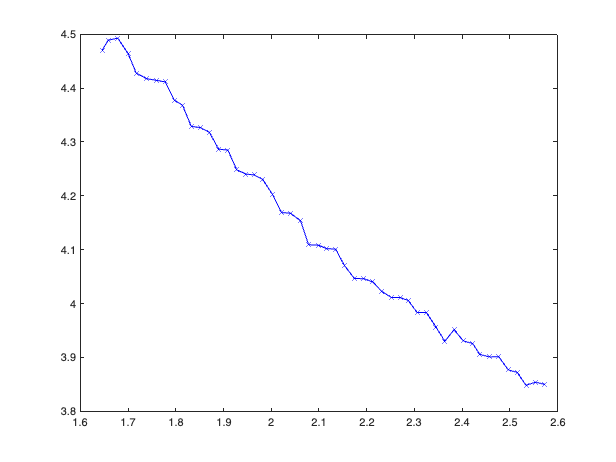


figure();
plot(AuS9a_dac, AuS9a_ratio, "b-x");